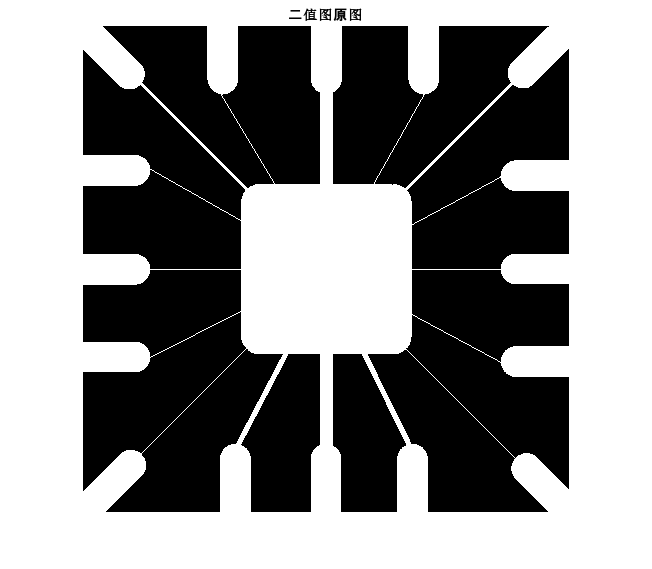

clear
img = imread('E:\Books\书本完整图片库\DIP3E_Original_Images_CH10\Fig1005(a)(wirebond_mask).tif');
figure;

imshow(img);

title('二值图原图');

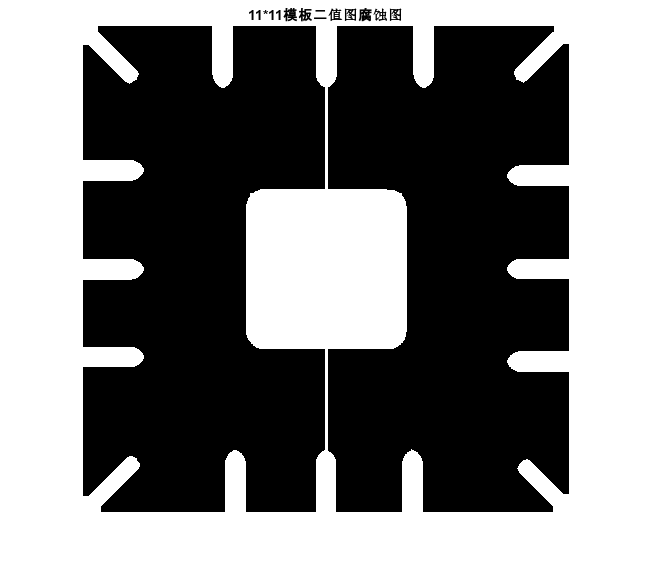


%腐蚀模板
mode11 = ones(11,11);
mode15 = ones(15,15);
mode45 = ones(45,45);

%腐蚀图像
erodedimage = imerode(img,mode11);

imshow(erodedimage);
title('11*11模板二值图腐蚀图');

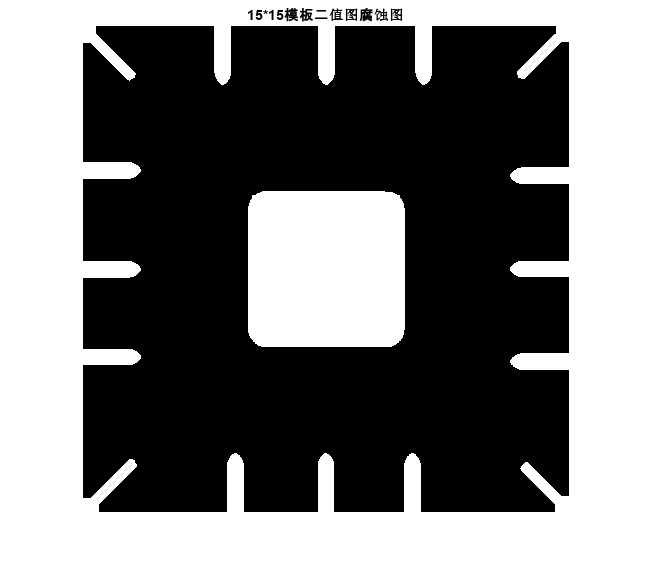


erodedimage = imerode(img,mode15);

imshow(erodedimage);
title('15*15模板二值图腐蚀图');

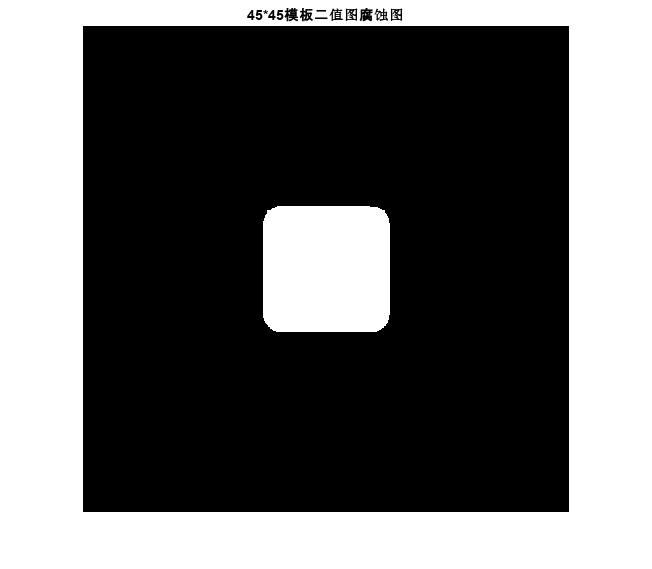


erodedimage = imerode(img,mode45);

imshow(erodedimage);
title('45*45模板二值图腐蚀图');

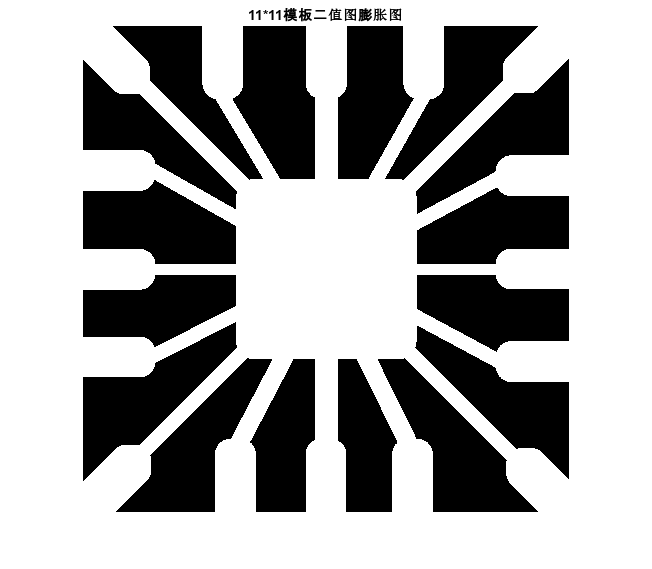


%膨胀图像
dilatedimage = imdilate(img,mode11);

imshow(dilatedimage);
title('11*11模板二值图膨胀图');

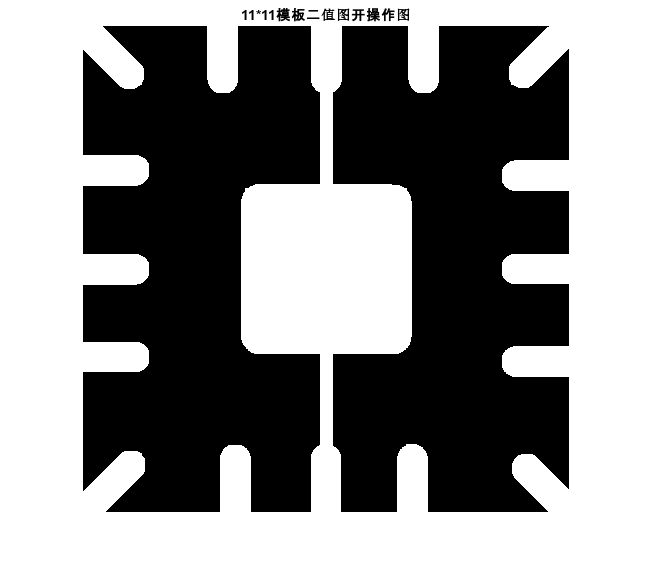


%先腐蚀后膨胀（开操作）
openimage = imdilate(imerode(img,mode11),mode11);

imshow(openimage);
title('11*11模板二值图开操作图');

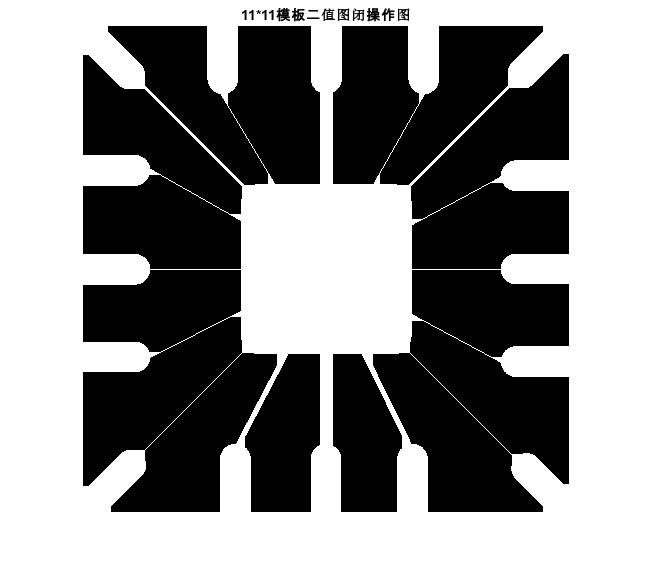



%先膨胀后腐蚀（闭操作）
closeimage = imerode(imdilate(img,mode11),mode11);

imshow(closeimage);
title('11*11模板二值图闭操作图');

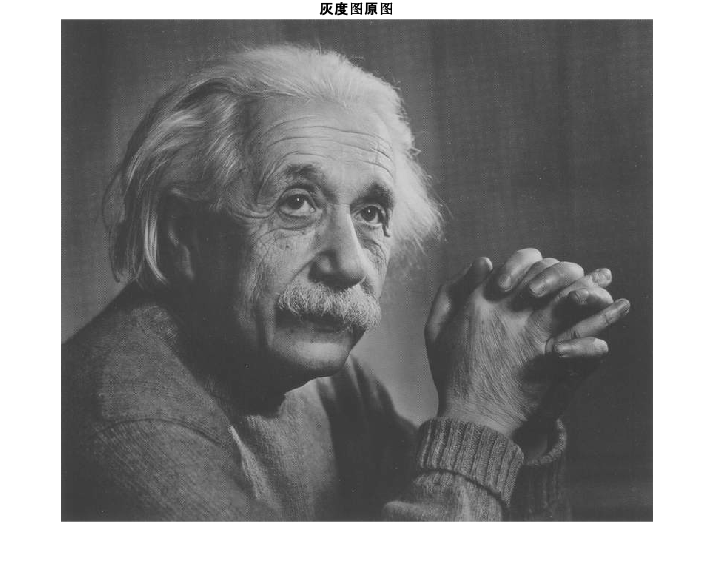

img = imread('E:\Books\书本完整图片库\DIP3E_Original_Images_CH02\Fig0241(b)(einstein med contrast).tif');

figure;
imshow(img);

title('灰度图原图');

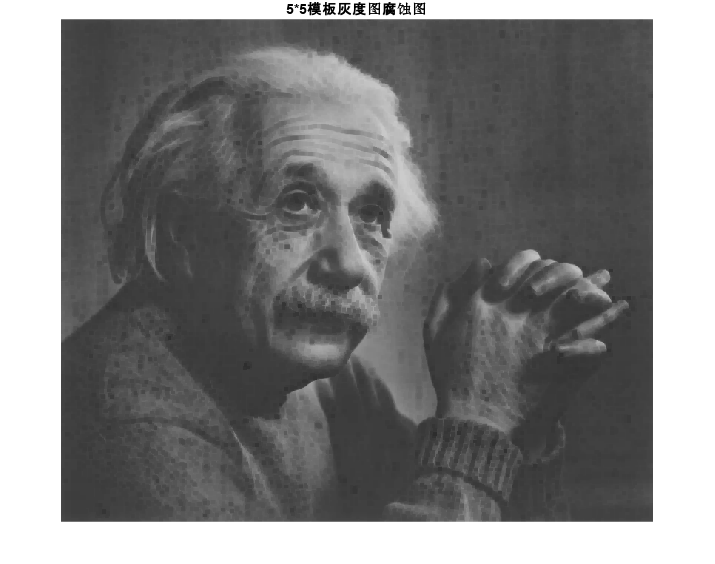


%腐蚀模板
mode = ones(5,5);

%腐蚀图像
erodedimage = imerode(img,mode);

imshow(erodedimage);
title('5*5模板灰度图腐蚀图');

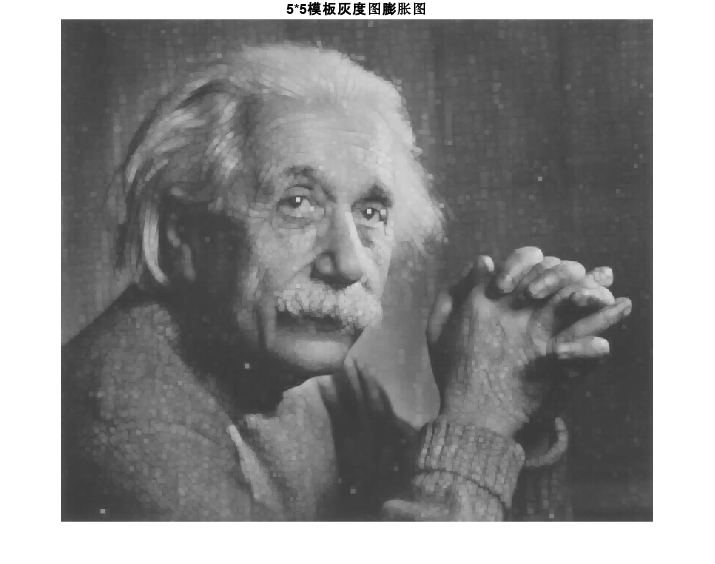


%膨胀图像
dilatedimage = imdilate(img,mode);

imshow(dilatedimage);
title('5*5模板灰度图膨胀图');

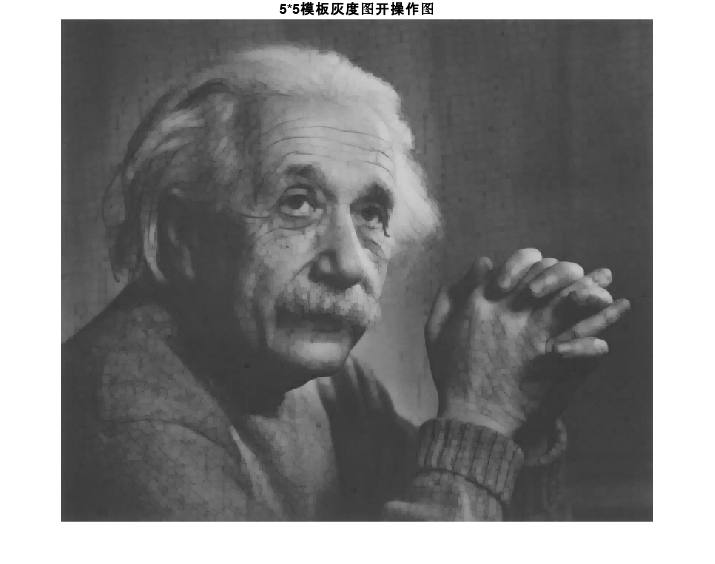


%先腐蚀后膨胀（开操作）
openimage = imdilate(imerode(img,mode),mode);

imshow(openimage);
title('5*5模板灰度图开操作图');

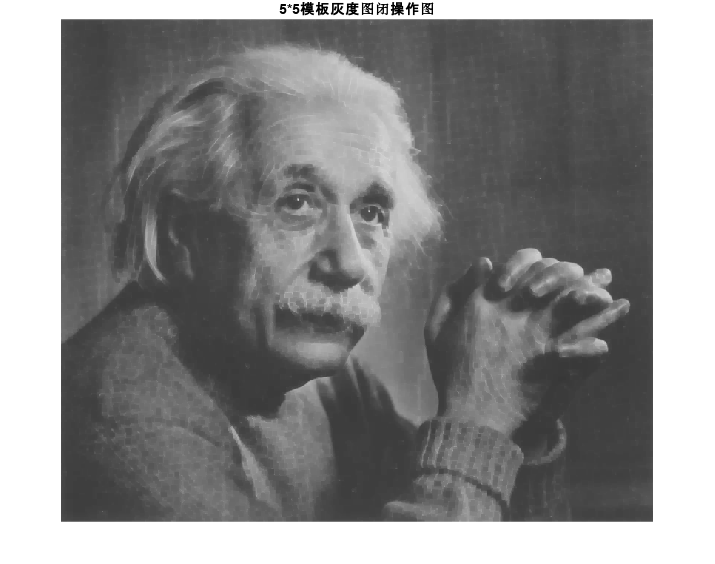



%先膨胀后腐蚀（闭操作）
closeimage = imerode(imdilate(img,mode),mode);

imshow(closeimage);
title('5*5模板灰度图闭操作图');